clear all
close all

%Define initial values of variables
x_initial = [50, 20, 10, 32, 100, 205, 12, 300, 120, 250, 56, 73, 15, 30, 10, 8, 50000000, 0.5, 20, 80, 44]

x_initial = 1.0e+07 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.0000    0.0000    0.0000    0.0000    0.0000



% Define Drag Coefficient Regression:
global cd_mdl
%Variables: [angle_alpha, angle_beta, angle_gamma, num_cars]
%Solutiuon: [Coefficient of Drag]
var = [15,30,10,3;15,15,10,3;50,30,20,3;15,50,20,3;15,15,10,7;30,50,10,15;15,15,20,7;15,30,10,15;50,50,10,3;30,15,20,3;50,30,20,7;15,15,20,3]; 
sol = [0.7306;0.49511;0.603478;0.865479;0.825286;1.33042;0.7927;1.16979;0.869678;0.51569;1.02362;0.438809];
cd_mdl=fitlm(var,sol);

%test costObj function
[totalCost] = costObj(x_initial)

totalCost = single
942708736


%Run GA
%%% Set lower and upper bounds
%lower and upper bounds for train optimization
lb_network = [1,1,1,1,1,1,1,1,1,1,1,1];
ub_network = [133,307,133,307,133,307,133,307,133,307,133,307];

%lower and upper bounds for train optimization
lb_train =[15,15,10,3];
ub_train =[50,50,20,15];

%lower and upper bounds for safety optimization
lb_safety = [0 0 0 0 25];
ub_safety = [5000000000 1 60 200 100];

%Set overall lower and upper bounds
lb_total = [lb_network, lb_train, lb_safety] 

lb_total =      1     1     1     1     1     1     1     1     1     1     1     1    15    15    10     3     0     0     0     0    25


ub_total = [ub_network, ub_train, ub_safety]

ub_total = 1.0e+09 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.0000    0.0000    0.0000    0.0000    0.0000


%%% Set GA parameters
lb = lb_total;
ub = ub_total;
intcon = [1,2,3,4,5,6,7,8,9,10,11,12,16]; 
nvars = 21;
nonlincon = @combinedNonlincon;
fun = @costObj;

%intcon for network and safety 
intcon_network = [1, 2, 3, 4,5, 6, 7,8,9,10,11,12,16];
intocon_train = [4];

%options copied from Quinn's code:
options = optimoptions('ga', ...
    'Display', 'iter', ...                          
    'PlotFcn', {@gaplotbestf, @gaplotbestindiv}, ... 
    'UseParallel', false, ...                        % switched to false
    'PopulationSize', 120, ...
    'EliteCount', ceil(0.15 * 120), ...             % 15% of population kept as elite
    'CrossoverFraction', 0.70, ...                   % 70% of population undergoes crossover
    'CrossoverFcn', @crossoverlaplace, ...          % good for real-valued obj funcs
    'MutationFcn', @mutationadaptfeasible, ...      % adaptive mutation but only in the feasible space
    'SelectionFcn', @selectiontournament, ...       % tournament selection
    'MaxGenerations', 50, ...
    'FunctionTolerance', 1e-2, ...                  % stop if improvement in func value is very small
    'ConstraintTolerance', 1e-6, ...                % tight, but not zero, tolerance on constraints -->changed from 1e-3 to 0
    'InitialPenalty', 50, ...
    'PenaltyFactor', 1000, ...                       % quickly increase penalties for violating constraints
    'MaxStallGenerations', 20);                     % stop if no improvement (beyond tolerance) after 20 generations

%Run GA
[x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb,ub,nonlincon,intcon,options);


Single objective optimization:
21 Variables
13 Integer variables
21 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible



%calculate individual scores
convenience_score = networkScore(x_star(1:12))
train_veloc = TrainVelocity(predict(cd_mdl,x_star(13:16)))
number_of_accidents = accident_count_function(x_star(16:21))

fval_individual = [convenience_score, train_veloc, number_of_accidents];

%calculate individual costs
network_cost = networkCost(x_star(1:12))
train_cost = TrainCost(x_star(16))
safety_cost = safety_system_cost_function(x_star(17:21))
costs_individual = [network_cost, train_cost, safety_cost]

%take output from ga and put it here 
x_star_train_network = x_star(1:16);
%x_star_train_network = [120	181	32	234	16	77	109	146	34	195	21	281	31.17124424	28.8394559	15.76329319	4];

%Initial Conditions
B = 50000000; %watt hours
A = 0.5;
S = 20; %[seconds]
t = 80; %ratio of speed to magnitude? [magnitude/meters/second]
V = 44; %max speed NEW
x0 = [B, A, S, t, V];

%lower and upper bounds for X
lb = [0 0 0 0 25];
up = [5000000000 1 60 200 100];

%run pattern search w/ starting point x0
[x_star,fval,exitflag,output] = patternsearch(@accident_count_function2,x0, [],[],[],[],lb,up)

%combine ga output and patternsearch output
x_total = [x_star_train_network, x_star]

%calculate final total cost
totalCost = costObj(x_total)

%calculate overall individual scores
convenience_score = networkScore(x_total(1:12))
train_veloc = TrainVelocity(predict(cd_mdl,x_total(13:16)))
number_of_accidents = accident_count_function(x_total(16:21))

fval_individual = [convenience_score, train_veloc, number_of_accidents];

%calculate individual costs
network_cost = networkCost(x_total(1:12))
train_cost = TrainCost(x_total(16))
safety_cost = safety_system_cost_function(x_total(17:21))
costs_individual = [network_cost, train_cost, safety_cost]

%options copied from Quinn's code:
options = optimoptions('ga', ...
    'Display', 'iter', ...                          
    'PlotFcn', {@gaplotbestf, @gaplotbestindiv}, ... 
    'UseParallel', false, ...                        % switched to false
    'PopulationSize', 120, ...
    'EliteCount', ceil(0.15 * 120), ...             % 15% of population kept as elite
    'CrossoverFraction', 0.70, ...                   % 70% of population undergoes crossover
    'CrossoverFcn', @crossoverlaplace, ...          % good for real-valued obj funcs
    'MutationFcn', @mutationadaptfeasible, ...      % adaptive mutation but only in the feasible space
    'SelectionFcn', @selectiontournament, ...       % tournament selection
    'MaxGenerations', 50, ...
    'FunctionTolerance', 1e-2, ...                  % stop if improvement in func value is very small
    'ConstraintTolerance', 1e-6, ...                % tight, but not zero, tolerance on constraints -->changed from 1e-3 to 0
    'InitialPenalty', 50, ...
    'PenaltyFactor', 1000, ...                       % quickly increase penalties for violating constraints
    'MaxStallGenerations', 20);                     % stop if no improvement (beyond tolerance) after 20 generations

% Sensitivity Analysis parameter sweep
% Sensitivity coefficients give the rate of change of the optimal values of
% the objective relative to small changes in the values of the constraints

% Constraints to sweep:
% Government Study comes out on train safety causing a mandate to regulate all train maximum speeds to ___.
% Government grant comes out for public transport, all costs to build stations are now halved.
% maxAccidentCount

%need to set these values as global variables
% [minCars, dist, maxAccidentCount]

%Initial Conditions
B = 50000000; %watt hours
A = 0.5;
S = 20; %[seconds]
t = 80; %ratio of speed to magnitude? [magnitude/meters/second]
V = 44; %max speed NEW
x0_safety = [B, A, S, t, V];
    
%lower and upper bounds for X
lb_safety = [0 0 0 0 25];
up_safety = [5000000000 1 60 200 100];
    

%DistCon Parameter Sweep
% values tested: (20, 25, 30, 35, 40, 45, 50, 55, 60)
% GA run 10 times per value - change to once per value

%Set defaults:
minCars = 6;
dist = 35;
maxAccidentCount = 3;

setGlobalConstraintVars(minCars, dist, maxAccidentCount)

nonlincon = @combinedNonlinconSensitivityTesting;

%sweep dist hold other two parameters at defaults
x_star_sweep_dist = [x_initial]; %using x_initial just to set matrix size - probably a better way to do this
fval_sweep_dist = [];
sweep_vals_dist = [];

i = 45 %35, 40, 45

i = 45


Single objective optimization:
21 Variables
13 Integer variables
22 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240         0.09121           0.515        0
    2              360         0.06668          0.3856        0
    3              480         0.03935          0.2408        0
    4              600         0.03935          0.2485        1
    5              720         0.01679          0.1851        0
    6              840         0.01679           0.125        1
    7              960        0.003417          0.1419        0
    8             1080        0.003417          0.1147        1
    9             1200        0.003417          0.1279        2
   10         

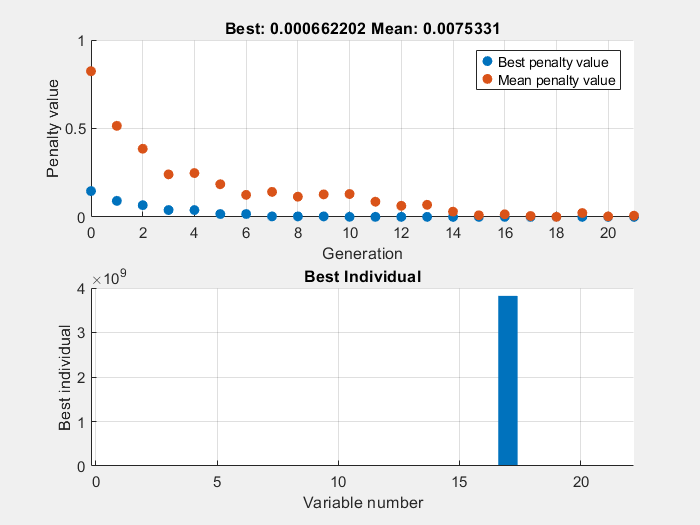

%set constraint values
setGlobalConstraintVars(minCars, i, maxAccidentCount)

%run GA 10 times per value - changed to once
%for j = 1:10 
[x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb,ub,nonlincon,intcon,options);

%take output from ga and put it here 

x_star_train_network = x_star(1:16);

%run pattern search w/ starting point x0
[x_star,fval,exitflag,output] = patternsearch(@accident_count_function2,x0_safety, [],[],[],[],lb_safety,up_safety)

patternsearch stopped because the mesh size was less than options.MeshTolerance.


x_star = 1.0e+09 *

    4.3450    0.0000    0.0000    0.0000    0.0000


fval = 0

exitflag = 1

output = struct with fields:
         function: @accident_count_function2
      problemtype: 'boundconstraints'
       pollmethod: 'gpspositivebasis2n'
    maxconstraint: 0
     searchmethod: []
       iterations: 26
        funccount: 173
         meshsize: 9.5367e-07
         rngstate: [1×1 struct]
          message: 'patternsearch stopped because the mesh size was less than options.MeshTolerance.'



%combine ga output and patternsearch output
x_total = [x_star_train_network, x_star]

x_total = 1.0e+09 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    4.3450    0.0000    0.0000    0.0000    0.0000



%calculate final total cost
totalCost = costObj(x_total)

totalCost = single
1.3630e+09


% %save values
% x_star_sweep_dist(end+1,:) = x_total;
% fval_sweep_dist(end+1) = totalCost;
% sweep_vals_dist(end+1) = i;
% 
% fval_sweep_dist = fval_sweep_dist';
% sweep_vals_dist = sweep_vals_dist';

%calculate overall individual scores
convenience_score = networkScore(x_total(1:12))

convenience_score = single
0.4990

train_veloc = TrainVelocity(predict(cd_mdl,x_total(13:16)))

train_veloc = 65.7985

number_of_accidents = accident_count_function(x_total(16:21))

number_of_accidents = 0


fval_individual = [convenience_score, train_veloc, number_of_accidents];

%calculate individual costs
network_cost = networkCost(x_total(1:12))

network_cost = single
572875008

train_cost = TrainCost(x_total(16))

train_cost = 140000000

safety_cost = safety_system_cost_function(x_total(17:21))

safety_cost = 6.5016e+08

costs_individual = [network_cost, train_cost, safety_cost]

costs_individual = 1×3 single row vector
   572875008   140000000   650158464


%minCars Parameter Sweep
% values tested: (0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10)
% GA run 10 times per value
% set defaults:
minCars = 6;
dist = 35;
maxAccidentCount = 3;

setGlobalConstraintVars(minCars, dist, maxAccidentCount)

%sweep minCars hold other two parameters at defaults
x_star_sweep_minCars = [x_initial]; %using x_initial just to set matrix size - probably a better way to do this
fval_sweep_minCars = [];
sweep_vals_minCars = [];

i = 3 %3, 4, 5
%set constraint values
setGlobalConstraintVars(i, dist, maxAccidentCount)

%run GA 10 times per value
% for j = 1:10
[x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb,ub,nonlincon,intcon,options);

%take output from ga and put it here 
x_star_train_network = x_star(1:16);

%run pattern search w/ starting point x0
[x_star,fval,exitflag,output] = patternsearch(@accident_count_function2,x0_safety, [],[],[],[],lb_safety,up_safety)

%combine ga output and patternsearch output
x_total = [x_star_train_network, x_star]

%calculate final total cost
totalCost = costObj(x_total)

% %save values
% x_star_sweep_minCars(end+1, :) = x_total;
% fval_sweep_minCars(end+1) = totalCost;
% sweep_vals_minCars(end+1) = i;
%end
% fval_sweep_minCars = fval_sweep_minCars';
% sweep_vals_minCars = sweep_vals_minCars';

%Accident Count Parameter Sweep
% values tested: (0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10)
% GA run 10 times per value


nonlincon = @combinedNonlinconSensitivityTesting;

% set defaults:
minCars = 6;
dist = 35;
maxAccidentCount = 3;

setGlobalConstraintVars(minCars, dist, maxAccidentCount)

%sweep maxAccidentCount hold other two parameters at defaults
x_star_sweep_accidents = [x_initial]; %using x_initial just to set matrix size - probably a better way to do this
fval_sweep_accidents = [];
sweep_vals_accidents = [];

i = 1; %1, 2, 3

%set constraint values
setGlobalConstraintVars(minCars, dist, i)

%run GA 10 times per value
% for j = 1:10
[x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb_total,ub_total,nonlincon,intcon,options);

%take output from ga and put it here 
x_star_train_network = x_star(1:16);

%run pattern search w/ starting point x0 -- how to add constraint relaxing?
[x_star,fval,exitflag,output] = patternsearch(@accident_count_function2,x0_safety, [],[],[],[],lb_safety,up_safety)

%combine ga output and patternsearch output
x_total = [x_star_train_network, x_star]

%calculate final total cost
totalCost = costObj(x_total)

% %save values
% x_star_sweep_accidents(end+1,:) = x_star;
% fval_sweep_accidents(end+1) = fval;
% sweep_vals_accidents(end+1) = i;
% % end
% fval_sweep_accidents = fval_sweep_accidents';
% sweep_vals_accidents = sweep_vals_accidents';


dists = [35, 40, 45]

dists =     35    40    45


distscosts = [1.29E+09,1.39E+09,1.36E+09]

distscosts = 1.0e+09 *

    1.2900    1.3900    1.3600


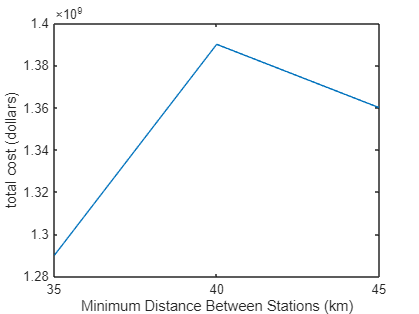

%plot values
figure()
plot(dists, distscosts)
xlabel("Minimum Distance Between Stations (km)")
ylabel("total cost (dollars)")